## Load Measurement Data

fig = openfig('Con_3point_4k_30sec.fig');
%% Find plotted lines
ax = findobj(fig, 'Type', 'Axes')

ax =   Axes with properties:

             XLim: [0 120000]
             YLim: [-4 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


stairsObj = findobj(ax, 'Type', 'Stair');

FRF.dTime = stairsObj(1).XData(:);
FRF.d = stairsObj(1).YData(:);

FRF.uTime = stairsObj(2).XData(:);
FRF.u = stairsObj(2).YData(:);

FRF.yTime = stairsObj(3).XData(:);
FRF.y = stairsObj(3).YData(:);

%% Measurement Constants
fs = 4000;                               %% Insert actual sampling freq! 
Ts = 1/fs;
L = length(FRF.u);

## Estimate H(f)

## PSD/CPSD Constants

NrWin = 120

NrWin = 120

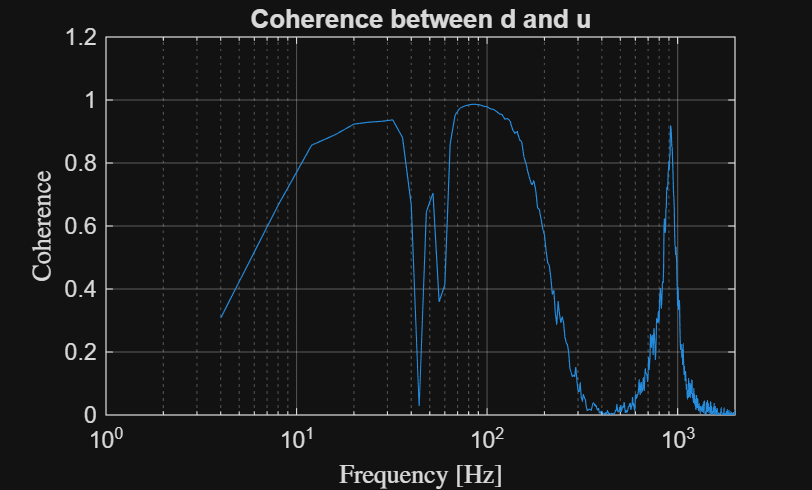

nfft = L/NrWin;                                      %% Window length [# samples]
noverlap = .5*nfft;                                   %% Nr of overlapped samples [# samples]

[PSD.Sud, hz] = cpsd(FRF.d, FRF.u,hann(nfft),noverlap,nfft,fs);
PSD.Sdd = pwelch(FRF.d,hann(nfft),noverlap,nfft,fs);

PSD.coherence_du = mscohere(FRF.d,FRF.u,hann(nfft),noverlap,nfft,fs);
% Plot coherence
figure;
semilogx(hz, PSD.coherence_du);
title('Coherence between d and u')
grid on;
xlabel('Frequency [Hz]', Interpreter='latex')
ylabel('Coherence', Interpreter='latex')
ylim([0 1.2])

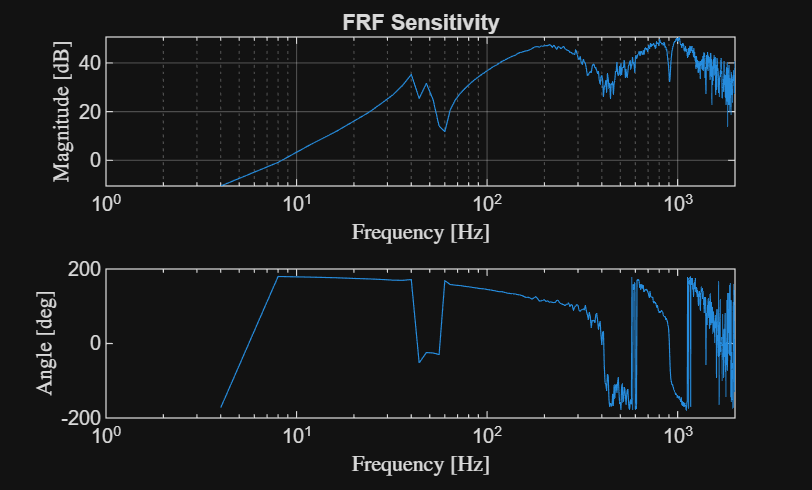


S = PSD.Sud./PSD.Sdd;

% plot S
S_mag = 20*log10(abs(S));
S_ph = angle(S) * (180/pi);
figure;
subplot(2,1,1)
semilogx(hz,S_mag);
title("FRF Sensitivity")
grid on;
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Magnitude [dB]',Interpreter="latex")
subplot(2,1,2)
semilogx(hz,S_ph)
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Angle [deg]',Interpreter="latex")


freqRes = fs/nfft

freqRes = 4

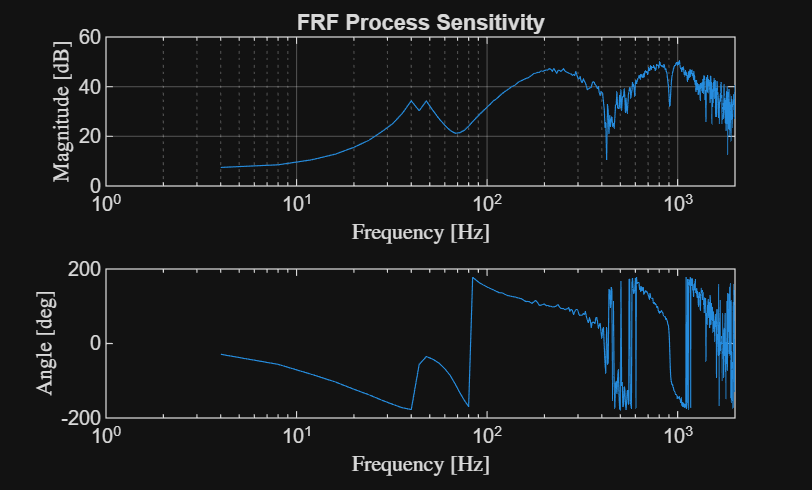


% Estimate Process Sensitivity
PSD.Syd = cpsd(FRF.d, FRF.y,hann(nfft),noverlap,nfft,fs);
PS = PSD.Syd./PSD.Sdd;

PS_mag = 20*log10(abs(PS));
PS_ph = angle(PS) * (180/pi);
figure;
subplot(2,1,1)
semilogx(hz,PS_mag);
title("FRF Process Sensitivity")
grid on;
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Magnitude [dB]',Interpreter="latex")
subplot(2,1,2)
semilogx(hz,PS_ph)
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Angle [deg]',Interpreter="latex")

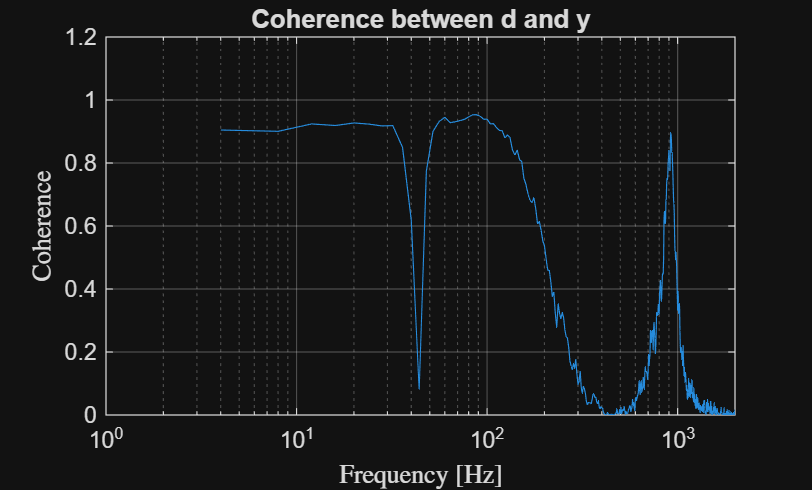


% Coherence of d and e
PSD.coherence_dy = mscohere(FRF.d,FRF.y,hann(nfft),noverlap,nfft,fs);
% Plot coherence
figure;
semilogx(hz, PSD.coherence_dy);
title('Coherence between d and y')
grid on;
xlabel('Frequency [Hz]', Interpreter='latex')
ylabel('Coherence', Interpreter='latex')
ylim([0 1.2])

## Transfer Function Estimation

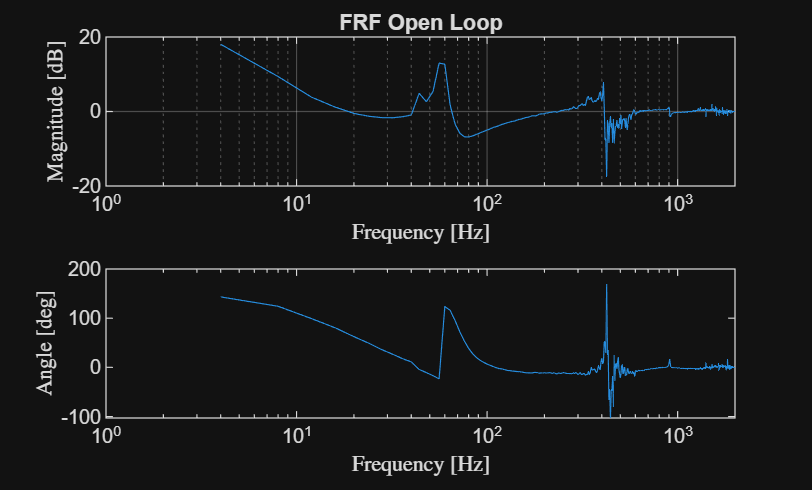

H = PS./S;

H_mag = 20*log10(abs(H));
H_ph = angle(H) * (180/pi);
figure;
subplot(2,1,1)
semilogx(hz,H_mag);
title("FRF Open Loop")
grid on;
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Magnitude [dB]',Interpreter="latex")
subplot(2,1,2)
semilogx(hz,H_ph)
xlabel("Frequency [Hz]",Interpreter="latex")
ylabel('Angle [deg]',Interpreter="latex")